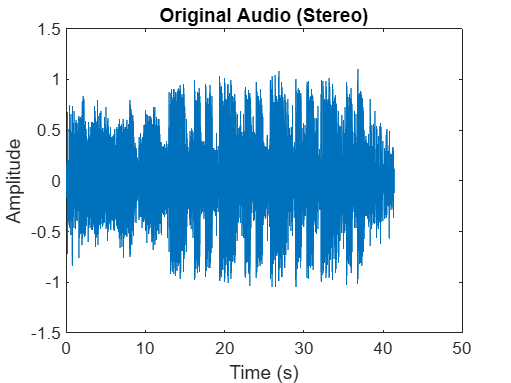

clc;
clear;

global player status_txt Fs;


[file, path] = uigetfile({'*.wav'}, 'Select an audio file');
if isequal(file, 0)
    disp('No file selected.');
    return;
end

[audioIn, Fs] = audioread(fullfile(path, file));
audioIn = mean(audioIn, 2); 
t = (0:length(audioIn)-1)/Fs;


vocalFilter = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 300, ...
    'HalfPowerFrequency2', 3400, ...
    'SampleRate', Fs);

instrFilter = designfilt('bandstopiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 300, ...
    'HalfPowerFrequency2', 3400, ...
    'SampleRate', Fs);


vocalPart = filtfilt(vocalFilter, audioIn);
instrumentalPart = filtfilt(instrFilter, audioIn);


figure('Name', 'Original Audio');
plot(t, audioIn);
title('Original Audio (Stereo)');
xlabel('Time (s)');
ylabel('Amplitude');

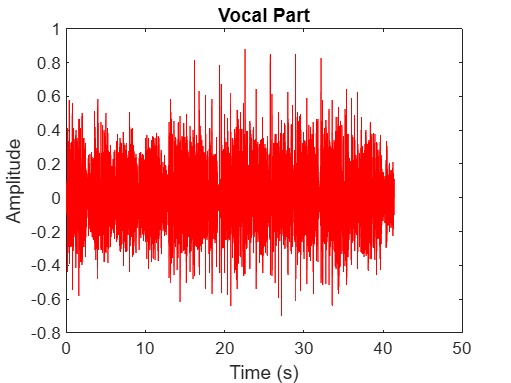


figure('Name', 'Vocal Part');
plot(t, vocalPart, 'r');
title('Vocal Part');
xlabel('Time (s)');
ylabel('Amplitude');

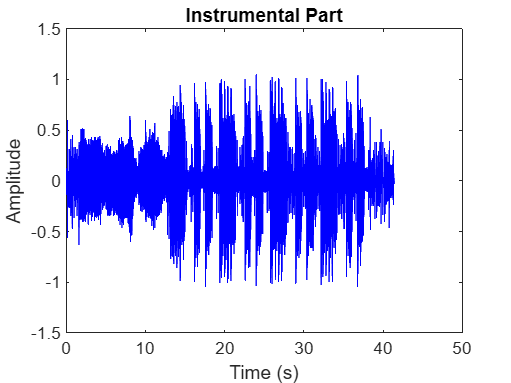


figure('Name', 'Instrumental Part');
plot(t, instrumentalPart, 'b');
title('Instrumental Part'); 
xlabel('Time (s)');
ylabel('Amplitude');



n = length(audioIn);
f = Fs*(0:(n/2))/n;

fft_original = abs(fft(audioIn)/n);
fft_vocal = abs(fft(vocalPart)/n);
fft_instr = abs(fft(instrumentalPart)/n);

figure('Name', 'FFT Spectrum');
plot(f, fft_original(1:n/2+1), 'k');

hold on;
plot(f, fft_vocal(1:n/2+1), 'r');

plot(f, fft_instr(1:n/2+1), 'b');

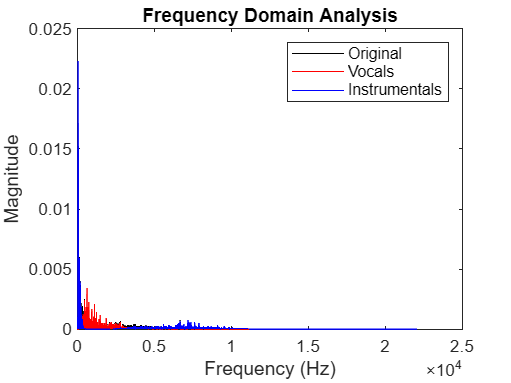

xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Original', 'Vocals', 'Instrumentals');
title('Frequency Domain Analysis');

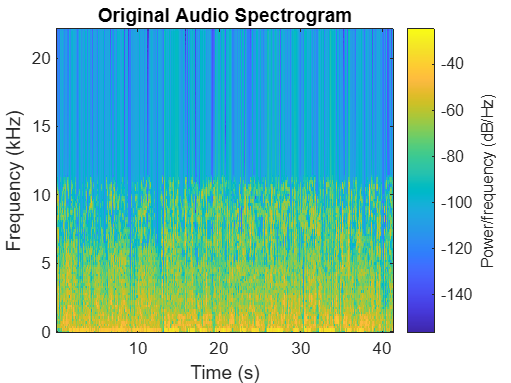



figure('Name', 'Spectrogram - Original Audio');
spectrogram(audioIn, 256, [], [], Fs, 'yaxis');
title('Original Audio Spectrogram');

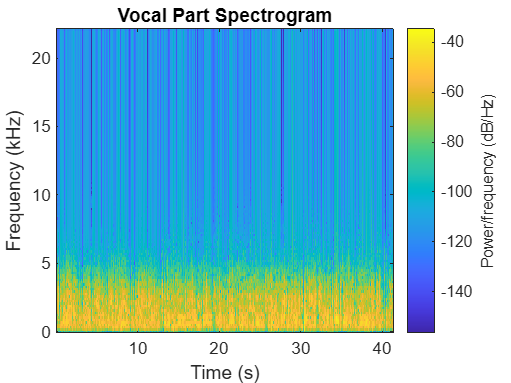


figure('Name', 'Spectrogram - Vocal Part');
spectrogram(vocalPart, 256, [], [], Fs, 'yaxis');
title('Vocal Part Spectrogram');

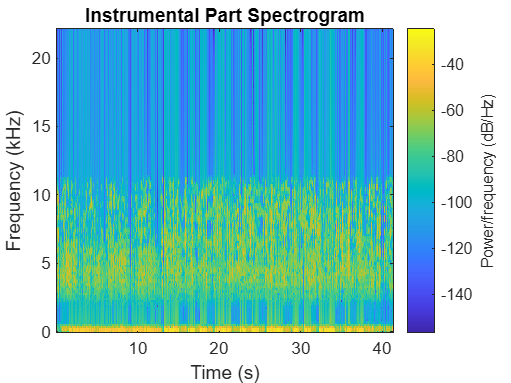


figure('Name', 'Spectrogram - Instrumental Part');
spectrogram(instrumentalPart, 256, [], [], Fs, 'yaxis');
title('Instrumental Part Spectrogram');

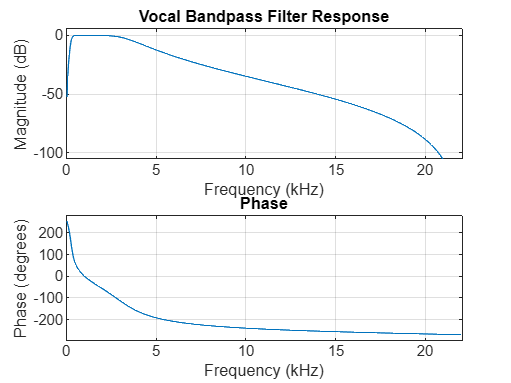



figure('Name', 'Bandpass Filter Response (Vocals)');
freqz(vocalFilter, 512, Fs);
title('Vocal Bandpass Filter Response');

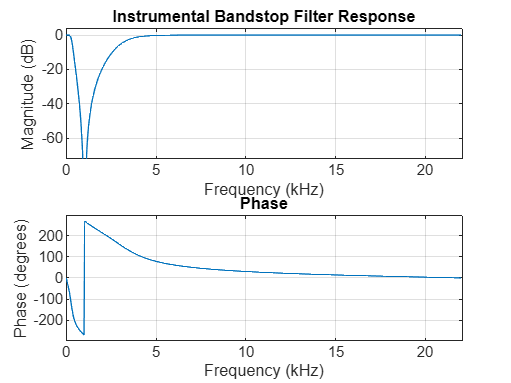


figure('Name', 'Bandstop Filter Response (Music)');
freqz(instrFilter, 512, Fs);
title('Instrumental Bandstop Filter Response');

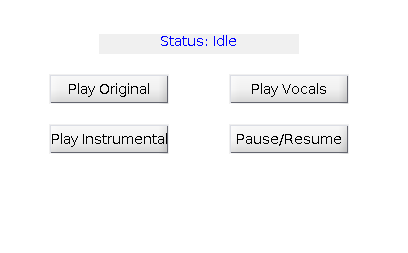



f_gui = figure('Name','Playback Controls','Position',[300 300 400 250]);

status_txt = uicontrol('Style','text','String','Status: Idle',...
    'Position',[100 200 200 20],'FontSize',10,'ForegroundColor','blue');


function playAudio(data, label)
    global player Fs status_txt;

    try
        stop(player);
    catch
    end

    player = audioplayer(data, Fs);
    set(status_txt, 'String', ['Status: Playing - ', label]);
    play(player);
end

% --- Toggle Pause/Resume Function
function togglePause()
    global player status_txt;
    if isempty(player)
        return;
    end

    if isplaying(player)
        pause(player);
        set(status_txt, 'String', 'Status: Paused');
    else
        resume(player);
        set(status_txt, 'String', 'Status: Playing');
    end
end


uicontrol('Style','pushbutton','String','Play Original',...
    'Position',[50 150 120 30],...
    'Callback', @(~,~) playAudio(audioIn, 'Original'));

uicontrol('Style','pushbutton','String','Play Vocals',...
    'Position',[230 150 120 30],...
    'Callback', @(~,~) playAudio(vocalPart, 'Vocals'));

uicontrol('Style','pushbutton','String','Play Instrumental',...
    'Position',[50 100 120 30],...
    'Callback', @(~,~) playAudio(instrumentalPart, 'Instrumental'));

uicontrol('Style','pushbutton','String','Pause/Resume',...
    'Position',[230 100 120 30],...
    'Callback', @(~,~) togglePause());



audiowrite('vocals_extracted.wav', vocalPart, Fs);
audiowrite('instrumental_extracted.wav', instrumentalPart, Fs);

disp('Audio saved as "vocals_extracted.wav" and "instrumental_extracted.wav"');

Audio saved as "vocals_extracted.wav" and "instrumental_extracted.wav"
